exit=0;
y_max=600;
x_max=300;
delta=0

delta = 0


x=x_max/2;
y=y_max/10;
app_y=y

app_y = 60

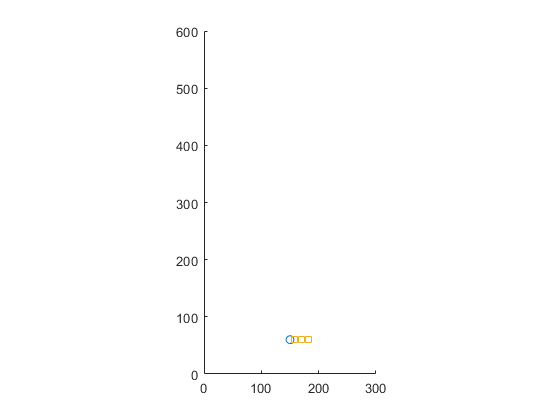


hold on
sprite=plot(x,y,'O');
bullet=[];
enemies=[];
bull0bj=plot(-10,-10,'o');
enem0bj=plot(-5,-5,'s');

axis manual
axis([0 300 0 600]);
daspect([1,1,1])

time_step=0.02;
space_step=2.5;

addpath('get_state')
level=0;
flag=0;
flip=5;
score=0;
flag8=1;

while ~exit
    [delta,fire,exit]=get_state();
    x=x+delta*space_step;
    if (x>x_max || x<0)
        exit=1;
        break
    end
    
    if fire
        flag=~flag;
    else
        flag=1;
    end
    
    set(sprite,'XData',[x],'Ydata',[y]);
    bullet=generate_bullet(bullet,fire*flag,x,y,y_max,space_step);
    app_y=app_y+space_step;
    
    if ~isempty(bullet)
        set(bull0bj,'XData',[bullet(:,1)],'Ydata',[bullet(:,2)]);
    else
        set(bull0bj,'XData',[-10],'Ydata',[-10]);
    end
    
    if ~isempty(enemies)
            if flag8==8;
                flip=-1*flip;
                flag8=0;
            else
                flag8=flag8+1;
            end
            
            
            enemies(:,1)=enemies(:,1)+flip;
            enemies(:,2)=enemies(:,2)-space_step;
            enemies(enemies(:,2)<0,:)=[];        
        set(enem0bj,'XData',[enemies(:,1)],'Ydata',[enemies(:,2)]);
    else
        set(enem0bj,'XData',[-5],'Ydata',[-5]);
    end
   
    
    [collision,enemies,hit,bullet,level]=check_enemies(bullet,enemies,level,x,y);
    if collision==1
        exit=1;
    end
    score=score+sum(hit);
    pause(time_step)
end